# Delta Haptic Device: Symbolic Kinematics and Circle Animation

The hand of the delta follows a horizontal circle $p(t)$. For each leg, `solve` gives the shoulder angle $q_i$ from the forearm-length equation, `diff` gives its velocity and acceleration, and `fanimator` / `playAnimation` animate the linkage.

**Conventions**

- Units: metres, radians, seconds (plots in degrees).

- $q_i > 0$: arm turned down, $q_i < 0$: arm up (same as `deltaIK` / `deltaFK` at the end).

- World frame: $z$ up, origin at the base centre on the base top.

**One leg** (side view): shoulder $A_i$ (fixed) $\rightarrow$ upper arm $L_a$ at angle $q_i$ $\rightarrow$ elbow $B_i$ $\rightarrow$ two parallel rods $L_b$ $\rightarrow$ hand attachment $C_i$.

clear; close all
% P = device parameters (same values as build_delta_haptic.m; m and deg)
P = struct('phi', [180 300 60], ...                                   % leg directions around the base
           'R',   [0.08094 0.0795402442896025 0.0788216942850955], ... % base centre -> shoulder, per leg
           't',   [-0.000298188371861643 -3.04440158298454e-05 0.000328632387691485], ... % sideways leg offset
           'H',   0.1241, 'La', 0.0721, 'Lb', 0.170, 'r', 0.034, 'w', 0.047, ...
           'qMid', -43.8987259894379, 'qMin', -85.038236404337, 'qMax', -2.75921557453871, ... % rope range
           'tiltMax', 13);                                       % rod-end tilt limit

## 1. Symbolic variables

Time $t$, the three shoulder angles $q_1, q_2, q_3$ and the hand position $p = (x, y, z)$, the centre of the hand's rod-end bolt plane.

t = sym('t', 'real');                 % t      : time (s)
q = sym('q', [3 1], 'real');          % q1..q3 : shoulder angle of leg 1, 2, 3 (rad)
syms x y z real                       % x y z  : hand position = centre of the hand's rod-end bolt plane (m)
p = [x; y; z];                        % p      : hand position vector

## 2. Parameters

- $R_i \approx 80$ mm: base centre to shoulder pivot (per leg, from the base screw holes)

- $T_i < 0.5$ mm: small sideways offset along the shoulder axis

- $H = 124.1$ mm: shoulder height above the base top

- $L_a = 72.1$ mm: upper arm, $L_b = 170$ mm: forearm rods, $r = 34$ mm: hand radius

- $w = 47$ mm: spacing of the two parallel rods, $\varphi_i = 180^\circ, 300^\circ, 60^\circ$: leg directions

R   = P.R;            % R(i)  : base centre -> shoulder pivot axis, radial distance of leg i (m, ~79-81 mm)
T   = P.t;            % T(i)  : small sideways offset of leg i along its pivot axis (m, < 0.5 mm)
H   = P.H;            % H     : height of the shoulder pivots above the base top (m, 124.1 mm)
La  = P.La;           % La    : upper arm, shoulder pivot -> elbow (m, 72.1 mm)
Lb  = P.Lb;           % Lb    : forearm, rod-end eye centre -> eye centre (m, 170 mm)
r   = P.r;            % r     : hand centre -> hand rod-end bolt line (m, 34 mm)
w   = P.w;            % w     : spacing of the 2 parallel forearm rods (m, 47 mm)
phi = deg2rad(P.phi); % phi(i): direction of leg i around the base, 180 / 300 / 60 deg (rad)

## 3. Points of each leg

Each leg is written in its own frame (turned $\varphi_i$ about $z$; $x$ out along the leg), then rotated to the world frame with $R_z$:


$$A_i = R_z \left[ R_i,\ T_i,\ H \right]^T \qquad
   B_i = R_z \left[ R_i + L_a\cos q_i,\ T_i,\ H - L_a\sin q_i \right]^T \qquad
   C_i = p + R_z \left[ r,\ 0,\ 0 \right]^T$$


for i = 1:3
    Rz   = [cos(phi(i)) -sin(phi(i)) 0; sin(phi(i)) cos(phi(i)) 0; 0 0 1];   % Rz : leg frame i -> world
    v{i} = Rz*[0; 1; 0];                                       % v_i : leg tangent = shoulder axis = rod-end bolt axis
    A{i} = Rz*[R(i); T(i); H];                                 % A_i : shoulder pivot (fixed)
    B{i} = Rz*[R(i) + La*cos(q(i)); T(i); H - La*sin(q(i))];   % B_i : elbow, end of the upper arm (moves with q_i)
    C{i} = p + Rz*[r; 0; 0];                                   % C_i : where the forearm meets the hand (moves with p)
end

## 4. The forearm-length equation (loop closure)

The two parallel rods act like one rod from $B_i$ to $C_i$, so each leg gives one equation with one unknown $q_i$:


$$\left| C_i - B_i \right|^2 = L_b^2$$


for i = 1:3
    eq(i) = sum((C{i} - B{i}).^2) == Lb^2; %#ok<SAGROW>      % eq(i) : one equation per leg, unknown q_i
end

## 5. Hand path: a horizontal circle

The circle is centred on the hand position with every arm at mid-travel, at constant height, 2 laps of 5 s. Its radius $R_c$ is 90 % of the largest circle that keeps every arm inside the rope end-stops and every rod end below 13° tilt (`maxRadius`):


$$p(t) = \left[ x_0 + R_c\cos\frac{2\pi t}{5},\ \ y_0 + R_c\sin\frac{2\pi t}{5},\ \ z_0 \right]$$


Tlap = 5;      % Tlap : time for one lap (s)
nLap = 2;      % nLap : number of laps
p0   = deltaFK(P.qMid*[1 1 1], P);   % p0 : centre of the circle = hand position with every arm at mid-travel
% Rc : circle radius (m) = 90 % of the largest circle inside the rope end-stops and the rod-end tilt limit
Rc = 0.9*maxRadius(P, p0(3), 1, p0(1:2));
pt = [p0(1) + Rc*cos(2*pi*t/Tlap);   % pt : hand position as a function of time, p(t)
      p0(2) + Rc*sin(2*pi*t/Tlap);
      p0(3) + 0*t];                  % 0*t keeps z a function of t (same height all the way round)

## 6. Solve for the shoulder angles (inverse kinematics)

Expanding the equation ($\cos^2 + \sin^2 = 1$ removes the squares) leaves


$$a\cos q_i + b\sin q_i + c = 0$$


The half-angle substitution $u = \tan(q/2)$, with $\cos q = \frac{1-u^2}{1+u^2}$ and $\sin q = \frac{2u}{1+u^2}$, turns it into a quadratic:


$$(c-a)\,u^2 + 2b\,u + (c+a) = 0 \quad\Rightarrow\quad
   q_i = 2\arctan\frac{b \pm \sqrt{a^2+b^2-c^2}}{a-c}$$


Two solutions (elbow out / elbow in); the elbow-out one, used by `deltaIK`, is kept.

syms u cq sq                     % u = tan(q/2); cq, sq = stand-ins for cos(q_i), sin(q_i)
qIK  = sym(zeros(3,1));          % qIK  : shoulder angles as functions of the hand position x, y, z
qRef = deg2rad(deltaIK(p0, P)).';   % qRef : numeric answer at p0, used only to pick the right solution
for i = 1:3
    e = subs(expand(lhs(eq(i)) - rhs(eq(i))), [cos(q(i)) sin(q(i))], [cq sq]);  % e = 0 written in cq, sq
    a = subs(diff(e, cq), [cq sq], [0 0]);                 % a : coefficient of cos(q_i)
    b = subs(diff(e, sq), [cq sq], [0 0]);                 % b : coefficient of sin(q_i)
    c = subs(e, [cq sq], [0 0]) + La^2;                    % c : constant term (La^2*(cq^2 + sq^2) = La^2)
    sol = 2*atan(solve((c - a)*u^2 + 2*b*u + (c + a) == 0, u));   % sol : both solutions q = 2*atan(u)
    val = double(subs(sol, p, p0));                        % val : both solutions at p0 (numbers)
    [~, k] = min(abs(mod(val - qRef(i) + pi, 2*pi) - pi)); % k   : the one closest to the arms-up answer
    qIK(i) = sol(k);
end
vpa(qIK, 4)                      % show q1, q2, q3 (x, y, z) with 4 digits (the exact form has huge fractions)

$$ans = \begin{array}{l} \left(\begin{array}{c} -2.0\,\mathrm{atan}\left(\frac{2.187e+100\,\left(2.5e+7\,\sqrt{-4.0\,x^{4}-0.751\,x^{3}-\sigma_{3}+0.004771\,x^{2}\,y-\sigma_{2}+\sigma_{5}+0.0967\,x^{2}-0.751\,x\,y^{2}+0.0004479\,x\,y-0.751\,x\,z^{2}+0.1864\,x\,z+0.01239\,x-4.0\,y^{4}+0.004771\,y^{3}-\sigma_{1}+\sigma_{4}+0.04878\,y^{2}+0.004771\,y\,z^{2}-0.001184\,y\,z-2.909e-5\,y-4.0\,z^{4}+1.986\,z^{3}-0.1145\,z^{2}-0.03275\,z+0.001316}-7.21e+6\,z+8.948e+5\right)}{-1.094e+108\,x^{2}+5.503e+106\,x-1.094e+108\,y^{2}+6.522e+104\,y-1.094e+108\,z^{2}+2.714e+107\,z+1.407e+106}\right)\\ 2.0\,\mathrm{atan}\left(\frac{6.806e+38\,\left(2.5e+7\,\sqrt{-4.0\,x^{4}+0.3639\,x^{3}-\sigma_{3}-0.6313\,x^{2}\,y-\sigma_{2}+\sigma_{5}+0.06233\,x^{2}+0.3639\,x\,y^{2}-0.04332\,x\,y+0.3639\,x\,z^{2}-0.09032\,x\,z-0.006054\,x-4.0\,y^{4}-0.6313\,y^{3}-\sigma_{1}+\sigma_{4}+0.08729\,y^{2}-0.6313\,y\,z^{2}+0.1567\,y\,z+0.01049\,y-4.0\,z^{4}+1.986\,z^{3}-0.1134\,z^{2}-0.03301\,z+0.001298}-7.21e+6\,z+8.948e+5\right)}{3.403e+46\,x^{2}+9.056e+44\,x+3.403e+46\,y^{2}-1.564e+45\,y+3.403e+46\,z^{2}-8.446e+45\,z-4.353e+44}\right)\\ 2.0\,\mathrm{atan}\left(\frac{2.658e+36\,\left(2.5e+7\,\sqrt{-4.0\,x^{4}+0.354\,x^{3}-\sigma_{3}+0.6237\,x^{2}\,y-\sigma_{2}+\sigma_{5}+0.06329\,x^{2}+0.354\,x\,y^{2}+0.04443\,x\,y+0.354\,x\,z^{2}-0.08787\,x\,z-0.005955\,x-4.0\,y^{4}+0.6237\,y^{3}-\sigma_{1}+\sigma_{4}+0.0884\,y^{2}+0.6237\,y\,z^{2}-0.1548\,y\,z-0.01038\,y-4.0\,z^{4}+1.986\,z^{3}-0.1129\,z^{2}-0.03314\,z+0.00129}-7.21e+6\,z+8.948e+5\right)}{1.329e+44\,x^{2}+3.702e+42\,x+1.329e+44\,y^{2}+6.237e+42\,y+1.329e+44\,z^{2}-3.299e+43\,z-1.695e+42}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=8.0\,y^{2}\,z^{2}\\ \sigma_{2}=8.0\,x^{2}\,z^{2}\\ \sigma_{3}=8.0\,x^{2}\,y^{2}\\ \sigma_{4}=1.986\,y^{2}\,z\\ \sigma_{5}=1.986\,x^{2}\,z \end{array}$$

## 7. Position, velocity and acceleration along the circle

Substituting $p(t)$ gives $q(t)$; `diff` applies the chain rule, which builds the Jacobian $J^{-1}$ and the velocity-squared terms automatically:


$$\dot q = \frac{dq}{dt} = J^{-1}\dot p \qquad\qquad \ddot q = \frac{d^2 q}{dt^2}$$


q_t   = subs(qIK, p, pt);        % q_t   : shoulder angles q(t) (rad)
dq_t  = diff(q_t, t);            % dq_t  : shoulder angular velocity dq/dt (rad/s)
ddq_t = diff(q_t, t, 2);         % ddq_t : shoulder angular acceleration d2q/dt2 (rad/s^2)

## 8. Checks

The symbolic $q(t)$ is compared with the numeric inverse kinematics `deltaIK` at 13 times, and the whole path is checked against the rope end-stops and the 13° rod-end tilt limit.

% matlabFunction turns each symbolic result into a fast numeric function of t: qf(t), dqf(t), ...
qf = matlabFunction(q_t); dqf = matlabFunction(dq_t); ddqf = matlabFunction(ddq_t);
pf = matlabFunction(pt);
for tt = linspace(0, nLap*Tlap, 13)                       % tt : check times (s)
    assert(norm(qf(tt) - deg2rad(deltaIK(pf(tt), P)).') < 1e-9, 'q(t) does not match deltaIK');
end
tv = linspace(0, nLap*Tlap, 201);                                  % tv : time samples for the plots (s)
qs = rad2deg(cell2mat(arrayfun(qf, tv, 'UniformOutput', false))); % qs : q at every sample (deg), 3 x 201
ps = cell2mat(arrayfun(pf, tv, 'UniformOutput', false));          % ps : hand position at every sample (m)
assert(all(qs(:) > P.qMin & qs(:) < P.qMax), 'path leaves the rope limits');        % rope end-stops
assert(all(rodEndTilt(ps, P) < P.tiltMax, 'all'), 'path tilts a rod end past its limit');  % rod-end tilt
fprintf('circle radius %.1f mm at height %.1f mm; q in [%.1f %.1f] deg, max rod-end tilt %.1f deg\n', ...
    1e3*Rc, 1e3*p0(3), min(qs(:)), max(qs(:)), max(rodEndTilt(ps, P), [], 'all'));

circle radius 30.7 mm at height 313.2 mm; q in [-59.5 -31.2] deg, max rod-end tilt 10.8 deg


## 9. Shoulder angle, velocity and acceleration

Each arm swings once per lap; the three legs are 120° out of phase.

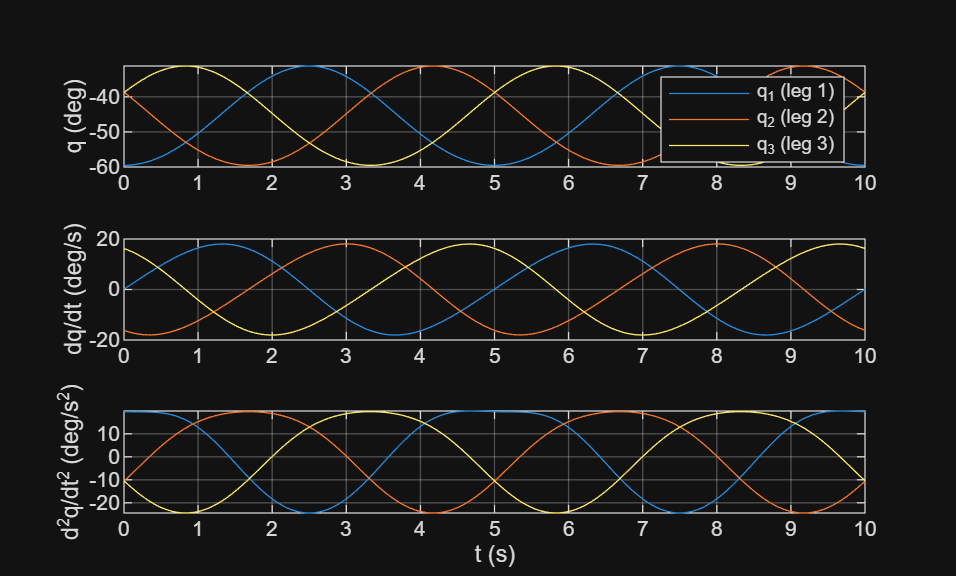

figure('Name', 'Shoulder kinematics')
lab = {'q (deg)', 'dq/dt (deg/s)', 'd^2q/dt^2 (deg/s^2)'}; fn = {qf, dqf, ddqf};
for k = 1:3
    subplot(3, 1, k)
    plot(tv, rad2deg(cell2mat(arrayfun(fn{k}, tv, 'UniformOutput', false))))
    grid on; ylabel(lab{k}); if k == 1, legend('q_1 (leg 1)', 'q_2 (leg 2)', 'q_3 (leg 3)'); end
end
xlabel('t (s)')

## 10. Animation

The elbow points $B_i(t)$ and hand points $C_i(t)$ are computed once for every frame, then `fanimator` draws the upper arms (red), the rod pairs (green), the hand (blue), the circle path (magenta, centre marked +) and a magenta dot on the hand centre.

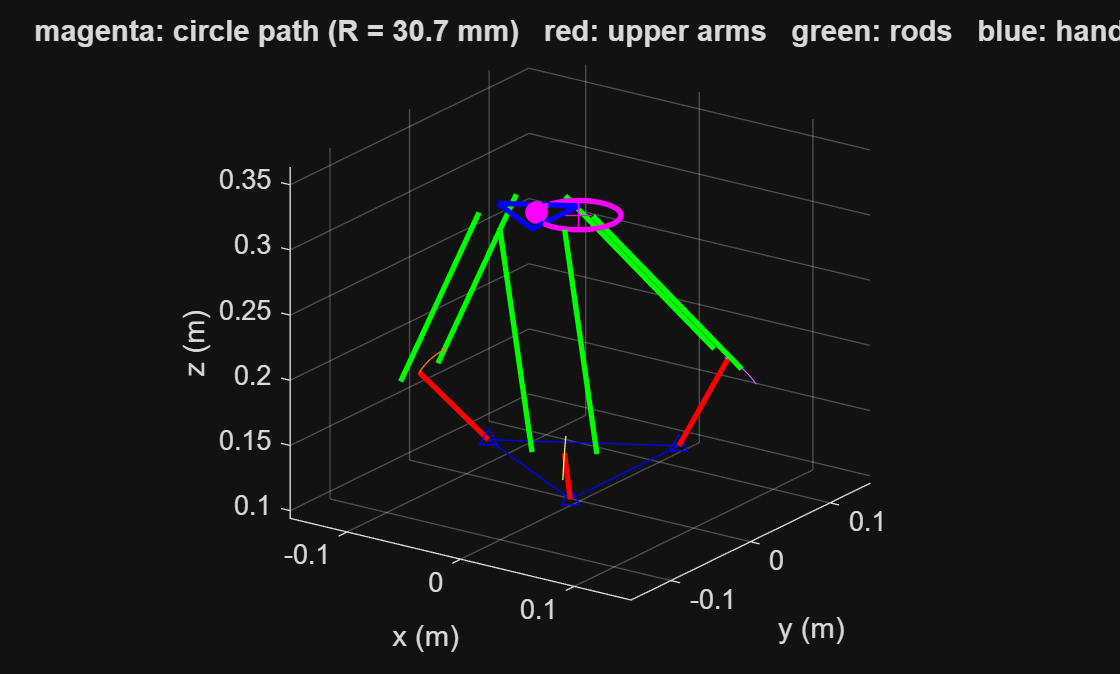

fps = 20;                        % fps : animation frames per second
tf  = 0:1/fps:nLap*Tlap;         % tf  : frame times (s)
for i = 1:3
    Bf = matlabFunction(subs(B{i}, q(i), q_t(i)), 'Vars', t);     % Bf(t) : elbow position B_i(t)
    Cf = matlabFunction(subs(C{i}, p, pt), 'Vars', t);            % Cf(t) : hand attachment C_i(t)
    Bn{i} = cell2mat(arrayfun(Bf, tf, 'UniformOutput', false));   % Bn{i} : elbow at every frame, 3 x frames
    Cn{i} = cell2mat(arrayfun(Cf, tf, 'UniformOutput', false));   % Cn{i} : hand attachment at every frame
end
fr = @(tt) round(tt*fps) + 1;    % fr(tt) : frame number of time tt
% Drawing functions of time: one per colour, all 3 legs in one line (fanimator needs one object per function);
% gap = NaN column splits one line into separate segments
gap = NaN(3,1);
H_arm     = @(tt) line3([A{1}, Bn{1}(:,fr(tt)), gap, A{2}, Bn{2}(:,fr(tt)), gap, A{3}, Bn{3}(:,fr(tt))], '-r');  % upper arms A->B
rodPair   = @(i, k) [Bn{i}(:,k) + w/2*v{i}, Cn{i}(:,k) + w/2*v{i}, gap, Bn{i}(:,k) - w/2*v{i}, Cn{i}(:,k) - w/2*v{i}, gap];  % 2 rods of leg i, w apart
H_forearm = @(tt) line3([rodPair(1, fr(tt)), rodPair(2, fr(tt)), rodPair(3, fr(tt))], '-g');                    % forearms B->C
H_hand    = @(tt) line3([Cn{1}(:,fr(tt)), Cn{2}(:,fr(tt)), Cn{3}(:,fr(tt)), Cn{1}(:,fr(tt))], '-b');              % hand triangle

figure('Name', 'Delta haptic animation')
hold on
Ab = [A{:} A{1}];
plot3(Ab(1,:), Ab(2,:), Ab(3,:), 'b^-')                      % blue triangles: shoulder pivots A_i (base)
for i = 1:3, plot3(Bn{i}(1,:), Bn{i}(2,:), Bn{i}(3,:)), end  % thin arcs: elbow paths B_i(t)
opts = {'AnimationRange', [0 nLap*Tlap], 'FrameRate', fps};
Pn = cell2mat(arrayfun(pf, tf, 'UniformOutput', false));     % Pn : hand centre at every frame
H_centre  = @(tt) plot3(Pn(1,fr(tt)), Pn(2,fr(tt)), Pn(3,fr(tt)), 'mo', 'MarkerSize', 8, 'MarkerFaceColor', 'm');  % moving hand centre
fanimator(H_arm, opts{:}); fanimator(H_forearm, opts{:}); fanimator(H_hand, opts{:}); fanimator(H_centre, opts{:});
th = linspace(0, 2*pi, 181);                                 % circle path p(t), drawn once
plot3(p0(1) + Rc*cos(th), p0(2) + Rc*sin(th), p0(3) + 0*th, '-m', 'LineWidth', 2)
plot3(p0(1), p0(2), p0(3), 'm+', 'MarkerSize', 10)            % circle centre
hold off
axis equal; grid on; view(35, 20); xlabel('x (m)'); ylabel('y (m)'); zlabel('z (m)')
axis([-0.15 0.15 -0.15 0.15 H - 0.03 p0(3) + 0.05])          % hand works above the shoulder pivots (arms up)
title(sprintf('magenta: circle path (R = %.1f mm)   red: upper arms   green: rods   blue: hand', 1e3*Rc))

playAnimation

## Local functions

Drawing helper and numeric kinematics (largest circle, rod-end tilt, forward and inverse kinematics).

function h = line3(M, style)   % plot the columns of a 3xN point matrix as one 3D line
    h = plot3(M(1,:), M(2,:), M(3,:), style, 'LineWidth', 2);
end

function R = maxRadius(P, z, margin, cxy)
% Largest radius (m) of a horizontal circle at height z (rod-end bolt plane, m), centred at cxy, on which every
% shoulder stays inside [qMin+margin, qMax-margin] deg and every rod end stays margin inside P.tiltMax.
% 0 if not even the centre point is reachable.
    th = linspace(0, 2*pi, 181);
    ok = @(r) all(arrayfun(@(a) inRange([cxy(1)+r*cos(a); cxy(2)+r*sin(a); z], P, margin), th));
    R = 0; if ~ok(0), return, end
    lo = 0; hi = 0.25;
    for it = 1:30, m = (lo+hi)/2; if ok(m), lo = m; else, hi = m; end, end
    R = lo;
end

function y = inRange(p, P, margin)
    q = deltaIK(p, P);
    y = all(rodEndTilt(p, P) < P.tiltMax - margin) && all(~isnan(q)) && all(q > P.qMin + margin) && all(q < P.qMax - margin);
end

function tilt = rodEndTilt(p, P)
% Rod-end misalignment (deg) per leg: how far each forearm leans sideways out of its leg plane.
% The rod-end bolts run along the leg tangent v_i at both ends, so tilt_i = asin(|d_i . v_i|) with rod direction
% d_i = (p + r u_i - E_i)/Lb and E_i . v_i = t_i:  tilt_i = asin(|p . v_i - t_i| / Lb). Depends on x, y only.
%   p : 3xN hand positions (rod-end bolt-plane centre, m)  ->  tilt : 3xN (deg)
    v = [-sind(P.phi); cosd(P.phi)].';               % 3x2 leg tangents
    tilt = asind(abs(v*p(1:2,:) - P.t(:)) / P.Lb);
end

function p = deltaFK(qdeg, P)
% Effector centre (rod-end bolt plane) from shoulder angles (q>0 = arm down). Intersects 3 spheres, returns upper solution.
% Per leg: pivot at radius P.R(i), leg plane offset P.t(i) along the tangent, height P.H.
    C = zeros(3,3);
    for i = 1:3
        c = cosd(P.phi(i)); s = sind(P.phi(i));
        rad = P.R(i) + P.La*cosd(qdeg(i)) - P.r;           % radial distance of shifted sphere centre
        C(:,i) = [rad*c - P.t(i)*s; rad*s + P.t(i)*c; P.H - P.La*sind(qdeg(i))];
    end
    % trilateration of equal-radius spheres
    ex = (C(:,2)-C(:,1))/norm(C(:,2)-C(:,1)); a = dot(ex, C(:,3)-C(:,1));
    ey = C(:,3)-C(:,1)-a*ex; ey = ey/norm(ey); ez = cross(ex,ey); d = norm(C(:,2)-C(:,1));
    b = dot(ey, C(:,3)-C(:,1)); x = d/2; y = (a^2+b^2-2*a*x)/(2*b);
    z = sqrt(P.Lb^2 - x^2 - y^2);
    p = C(:,1) + x*ex + y*ey + z*ez; if p(3) < C(3,1), p = C(:,1) + x*ex + y*ey - z*ez; end
end

function q = deltaIK(p, P)
% Shoulder angles (deg, q>0 = arm down) that put the effector centre (rod-end bolt plane) at p (3x1, m).
% Per leg: elbow E(q) = [R + La*cos q, t, H - La*sin q] in the leg frame must be Lb from the hand attachment point.
% Of the two solutions, returns the arms-up one (nearest P.qMid). NaN where p is out of reach.
    q = nan(1,3);
    for i = 1:3
        c = cosd(P.phi(i)); s = sind(P.phi(i));
        A = [c s 0; -s c 0; 0 0 1]*p + [P.r; 0; 0];        % attachment point in the leg frame
        dx = P.R(i) - A(1); dy = P.t(i) - A(2); dz = P.H - A(3);
        K = (P.Lb^2 - dx^2 - dy^2 - dz^2 - P.La^2)/(2*P.La); % dx*cos q - dz*sin q = K
        rho = hypot(dx, dz); if abs(K) > rho, continue, end
        al = atan2d(dz, dx); sol = -al + [1 -1]*acosd(K/rho);
        sol = mod(sol - P.qMid + 180, 360) - 180 + P.qMid;   % wrap near the working range
        [~, k] = min(abs(sol - P.qMid)); q(i) = sol(k);
    end
end